### **Assignment2**

### **200664P**

% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
d21 = 30e-4; 			% cm
d22 = 15e-4; 			% cm
%d21 = 47.2470e-4;       % E9 cm
%d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

Q3

x=A\b;
display(x)

x =     0.0007
    0.0000
    0.0011
   -0.0000
    0.0011
   -0.0000


Q4

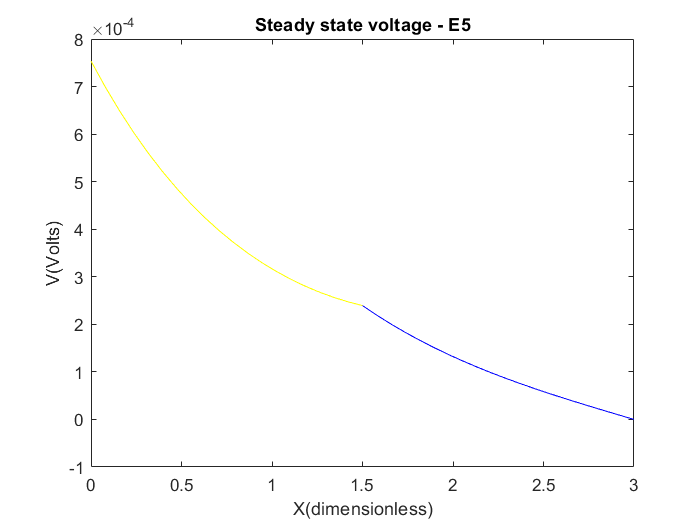

y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

Part a

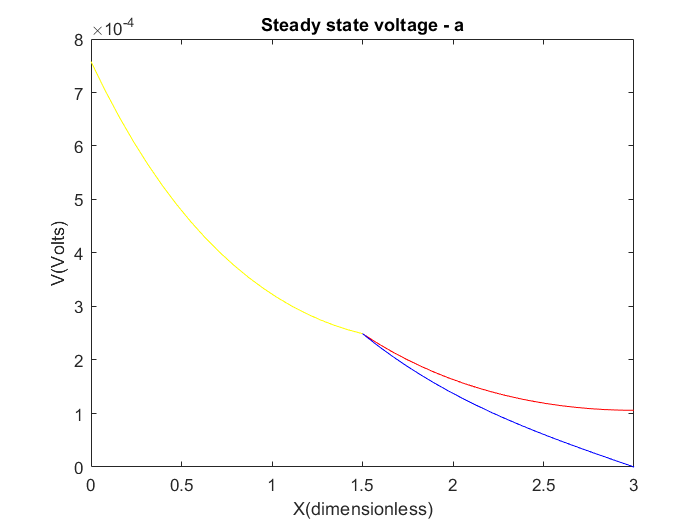

A1=A;
A1(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
x=A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - a');

Part b

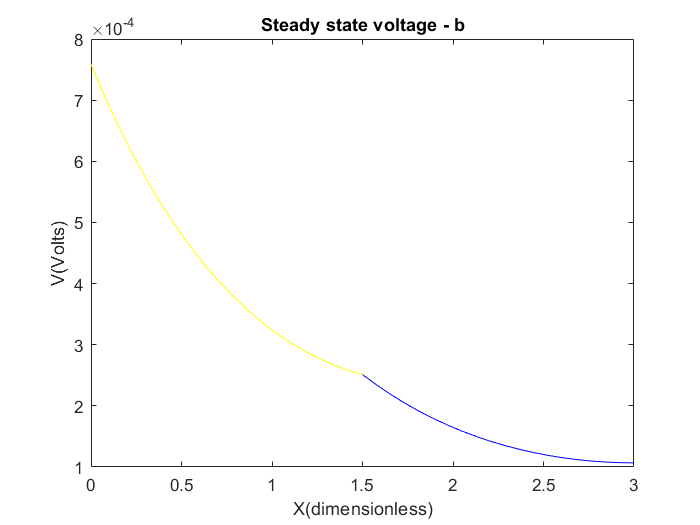

A1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x=A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - b');

Part c

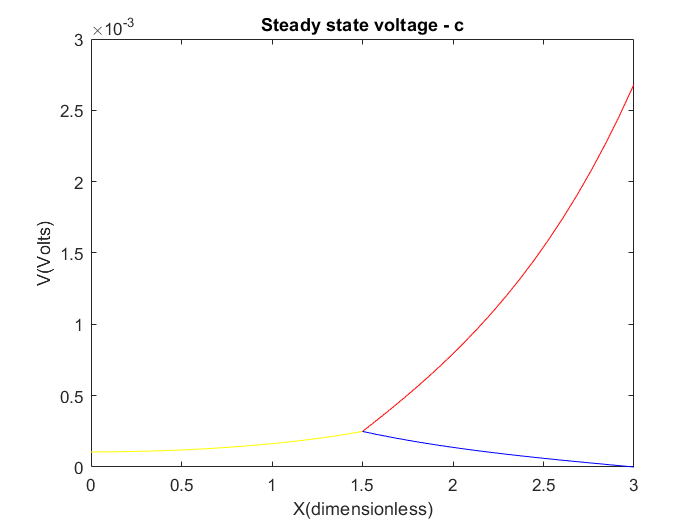

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0; 
b(2) = rl21*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - c');

Part d

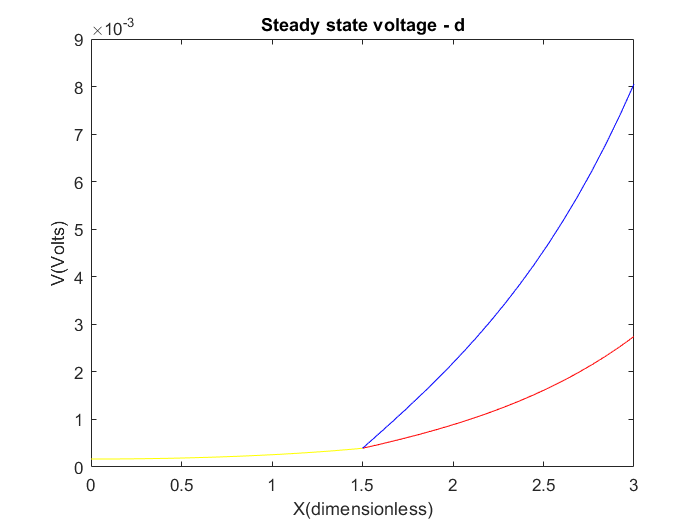

b(3) = rl22*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - d');

Question 5

Because, the current is received through that end of the daughter branches. The potential of that end is higher. Therefore, potential increases as X increases from 0, resulting in a positive gradient.

Question 6



d1 = 75e-4; 			% cm
%d21 = 30e-4; 			% cm
%d22 = 15e-4; 			% cm
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

Q6 - b

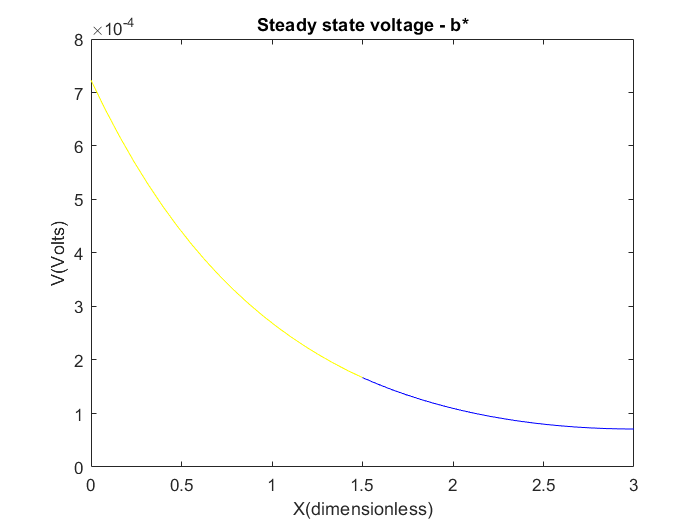

A1=A;
A1(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
A1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x=A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - b*');

Q6 - d

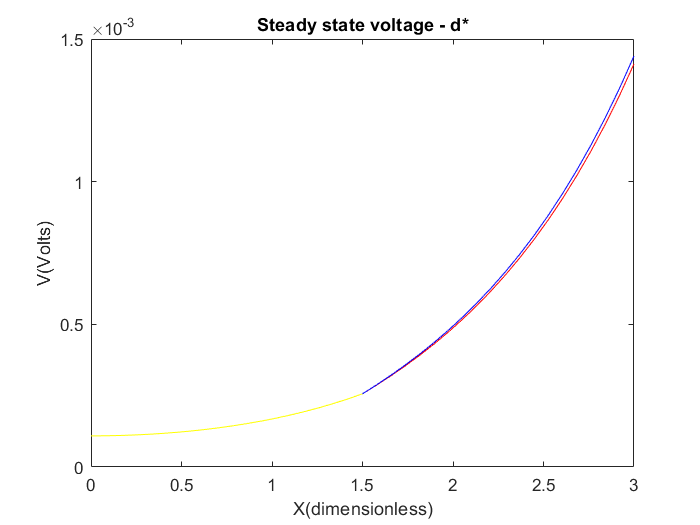

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0; 
b(2) = rl21*iapp;
b(3) = rl22*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - d*');

Here, the resistive forces of daughter branches are equal as the diameters are now similar. Therefore, when providing a current from the end of the daughter branches, the drop of action potential with the distance is similar. 